clear;
clc;
num = 500;
m = 0;
sigma = 1;

# **CA2-Q2-810101429**

#### ***A:***

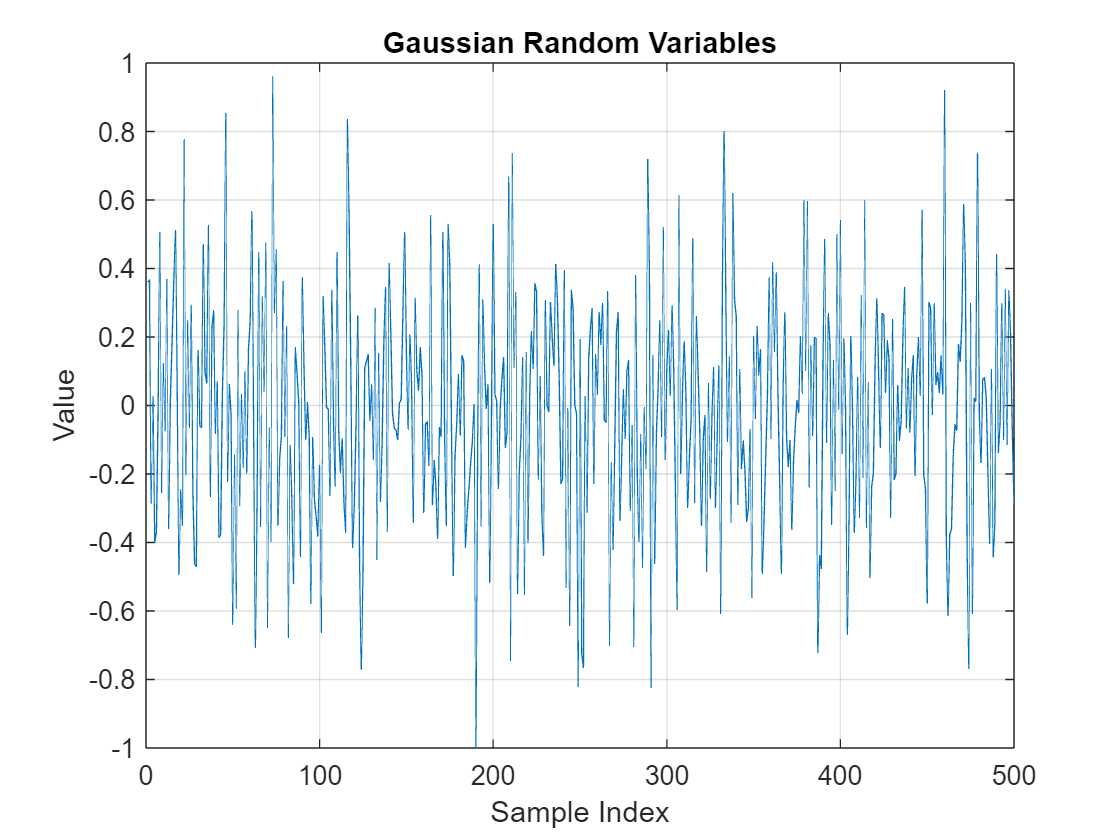

% Generating 500 rndom numbers with normal distribution of (0,1)
data = m + sigma * randn(num, 1);
data = data / max(abs(data));

figure;
plot(data, '-');
title('Gaussian Random Variables');
xlabel('Sample Index');
ylabel('Value');
grid on;

#### ***B:***

q = 64; %num of levels
v= log2(q); %num of required bits
quantization_step = 2/q; 

%quantization process
quantized_data = round((data - min(data)) / quantization_step);
quantized_data = quantized_data * quantization_step + min(data);

%quantization error
err_q = data - quantized_data;

% SQNR calculation
signal_power = mean(data.^2);
error_power = mean(err_q.^2);
SQNR = 10 * log10(signal_power / error_power);

disp(['SQNR: ', num2str(SQNR), ' dB']);

SQNR: 31.1213 dB


#### ***C:***

original_values = data(1:5);
quantized_values = quantized_data(1:5);
pcm_codes_dec = round((original_values - min(data)) / quantization_step); %PCM words in decimal
pcm_codes_bin = dec2bin(pcm_codes_dec,v); % PCM words in binary

disp('Original Values:');

Original Values:


disp(original_values);

    0.3609
    0.3662
   -0.2851
    0.0255
   -0.4008



disp('Quantized Values:');

Quantized Values:


disp(quantized_values); 

    0.3750
    0.3750
   -0.2812
    0.0312
   -0.4062



disp('PCM Codes in decimal:');

PCM Codes in decimal:


disp(pcm_codes_dec);

    44
    44
    23
    33
    19



disp('PCM Codes in binary:');

PCM Codes in binary:


disp(pcm_codes_bin);

101100
101100
010111
100001
010011


#### ***D:***

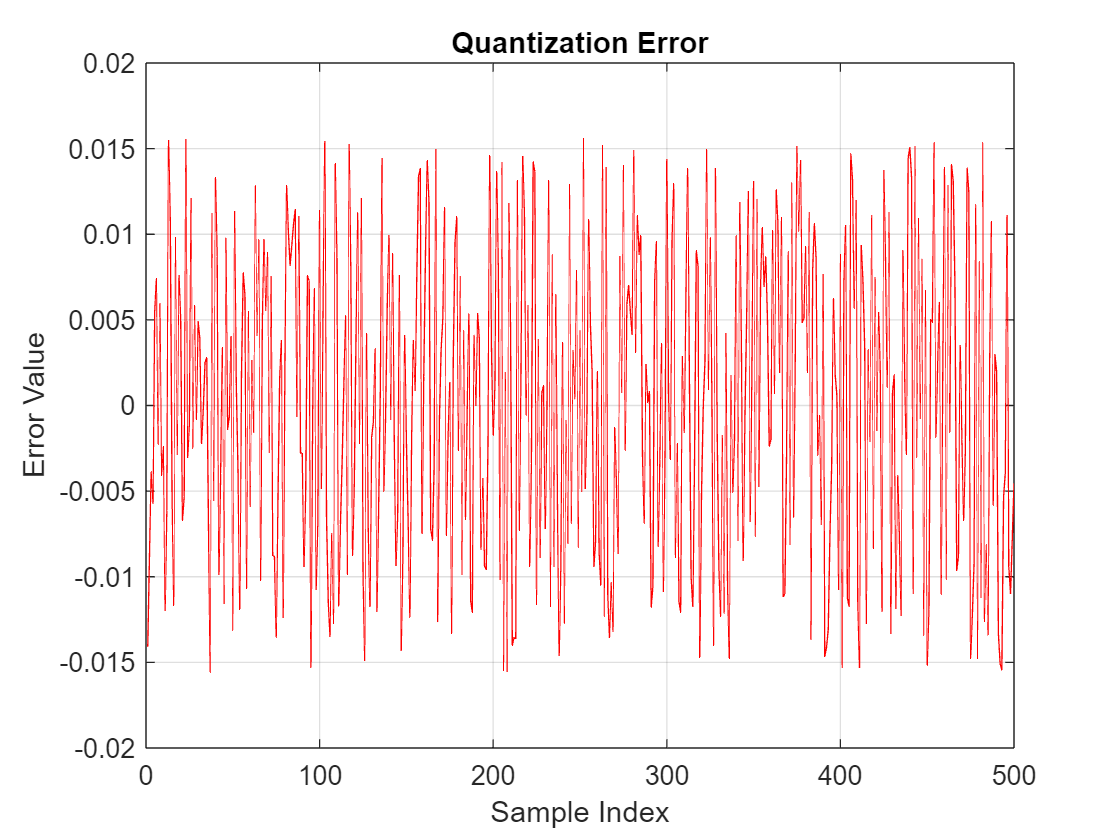


figure;
plot(err_q, 'r-');
title('Quantization Error');
xlabel('Sample Index');
ylabel('Error Value');
grid on;